# CONTROLLO AVANZATO___14/09/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## DEFINIZIONI

#### Variabili Simboliche 

syms px pz theta dpx dpz dtheta ddpx ddpz ddtheta T tau real

#### I-S-U

% Ingresso
u = [T;
     tau];

% Stato
x = [px;
     pz;
     theta;
     dpx;
     dpz;
     dtheta];

% Uscita
y = [px;
     pz;
     theta];

% Dimensioni
n = size(x,1);
m = 2;
p = size(y,1);

#### Parametri

m = 1.5;
J = 0.025;
g = 9.81;

#### Modello Dinamico Non Lineare

eq1_sym = ddpx == -(T/m)*sin(theta);
eq2_sym = ddpz == (T/m)*cos(theta) - g;
eq3_sym = ddtheta == tau/J;

eqs_sym = [eq1_sym;
           eq2_sym;
           eq3_sym];

% dx/dt
f = [dpx;
     dpz;
     dtheta;
     -(T/m)*sin(theta);
     (T/m)*cos(theta) - g;
     tau/J];

% y
g = y;

## LINEARIZZAZIONE

#### Punto di Equilibrio

x_bar = [0;
         1;
         0;
         0;
         0;
         0];

#### Ingresso di Equilibrio

peql = subs(eqs_sym, [theta, ddpx, ddpz, ddtheta], [0, 0, 0, 0]);

u_star = solve(peql, [T, tau], "ReturnConditions", true);


disp(table(double(u_star.T), double(u_star.tau)));

     Var1     Var2
    ______    ____

    14.715     0  



u_bar = [double(u_star.T);
         double(u_star.tau)];

#### Linearizzazione attorno a (x_bar, u_bar)

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);

A = double(subs(A_sym, [x; u], [x_bar; u_bar]));
B = double(subs(B_sym, [x; u], [x_bar; u_bar]));
C = double(subs(C_sym, [x; u], [x_bar; u_bar]));
D = double(subs(D_sym, [x; u], [x_bar; u_bar]));

sys = ss(A, B, C, D)


sys =
 
  A = 
          x1     x2     x3     x4     x5     x6
   x1      0      0      0      1      0      0
   x2      0      0      0      0      1      0
   x3      0      0      0      0      0      1
   x4      0      0  -9.81      0      0      0
   x5      0      0      0      0      0      0
   x6      0      0      0      0      0      0
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       0       0
   x4       0       0
   x5  0.6667       0
   x6       0      40
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


#### Stabilità

autovalori = eig(A); 

disp('Autovalori della matrice A:'); 

Autovalori della matrice A:


disp(autovalori);

     0
     0
     0
     0
     0
     0




if all(real(autovalori) < 0) 
    disp('Il sistema è ASINTOTICAMENTE STABILE '); 
elseif any(real(autovalori) > 0) 
    disp('Il sistema è INSTABILE a ciclo aperto.'); 
else    
    disp('Il sistema è STABILE'); 
end

Il sistema è STABILE


#### Controllabilità

if rank(ctrb(A,B)) == n
    disp('Il sistema è completamente controllabile');
else
    disp('Il sistema NON è completamente controllabile');
end

Il sistema è completamente controllabile


#### Osservabilità

if rank(obsv(A,C)) == n
    disp('Il sistema è completamente osservabile');
else
    disp('Il sistema NON è completamente osservabile');
end

Il sistema è completamente osservabile


## ASSEGNAMENTO AUTOVALORI CON METODO DI SYLVESTER

#### Specifiche

% Autovalori desiderati
eig_des = [-1.5, -2, -2.5, -3, -3.5, -4];

% Condizione iniziale
x0_sylv = [0.20;
           0.80;
           10;
           0;
           0;
           0];

#### Sintesi

Lambda = diag(eig_des);
G = rand(2,n);

X = sylvester(A, -Lambda, -B*G);
K_eig = -G/X

K_eig =    -0.1924   16.5168    1.0961   -0.2667    9.9376    0.1446
   -0.1198    4.0235    0.9892   -0.1848    1.2317    0.2469



A_cl_eig = A - B*K_eig;

disp(eig(A)); disp(eig(A_cl_eig));

     0
     0
     0
     0
     0
     0

   -4.0000
   -1.5000
   -3.5000
   -3.0000
   -2.5000
   -2.0000



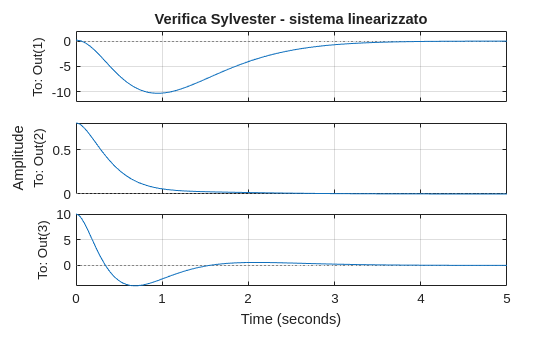

sys_eig = ss(A_cl_eig, B, C, D);

figure;
initial(sys_eig, x0_sylv);
grid on
title('Verifica Sylvester - sistema linearizzato');

out = sim('Verifica_SYLV_nonlinear.slx');

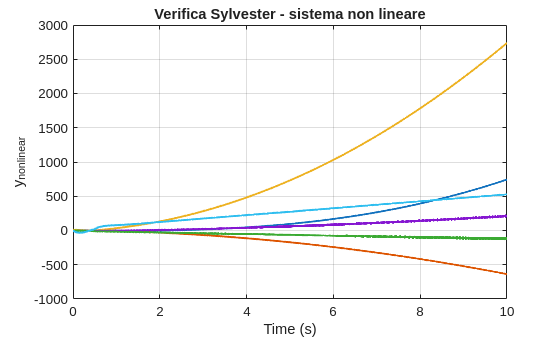


y1_nonlinear = squeeze(out.y1_nonlinear.Data);
y2_nonlinear = squeeze(out.y2_nonlinear.Data);
y3_nonlinear = squeeze(out.y3_nonlinear.Data);
y4_nonlinear = squeeze(out.y4_nonlinear.Data);
time = squeeze(out.y1_nonlinear.Time);

% Plot 
figure;
plot(time, y1_nonlinear, "LineWidth", 1.5);
hold on
plot(time, y2_nonlinear, "LineWidth", 1.5);
hold on
plot(time, y3_nonlinear, "LineWidth", 1.5);
hold on
plot(time, y4_nonlinear, "LineWidth", 1.5);
xlabel('Time (s)');
ylabel('y_{nonlinear}');
title('Verifica Sylvester - sistema non lineare');
grid on

## REGOLATORE LQR CON AZIONE INTEGRALE

#### Specifiche

% numero di variabili da aggiungere allo stato (errori)
z = 2;

% dimensione dello stato aumentato
n_tilde = n+z;

% Tempo di assestamento desiderato
Ts = 3.8;

alpha = 4/Ts;

% Riferimento
r = [1;
     1.5];

#### Sistema Aumentato

C_LQR = [1, 0, 0, 0, 0, 0;
         0, 1, 0, 0, 0, 0];

A_tilde = [A, zeros(n,z);
         -C_LQR, zeros(z,z)];

A_hat = A_tilde + alpha*eye(n_tilde);

B_tilde = [B;
           zeros(z,2)];

C_tilde = [C zeros(p,z)];

D_tilde = zeros(p,2);

sys_aum = ss(A_hat, B_tilde, C_tilde, D_tilde)


sys_aum =
 
  A = 
          x1     x2     x3     x4     x5     x6     x7     x8
   x1  1.053      0      0      1      0      0      0      0
   x2      0  1.053      0      0      1      0      0      0
   x3      0      0  1.053      0      0      1      0      0
   x4      0      0  -9.81  1.053      0      0      0      0
   x5      0      0      0      0  1.053      0      0      0
   x6      0      0      0      0      0  1.053      0      0
   x7     -1      0      0      0      0      0  1.053      0
   x8      0     -1      0      0      0      0      0  1.053
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       0       0
   x4       0       0
   x5  0.6667       0
   x6       0      40
   x7       0       0
   x8       0       0
 
  C = 
       x1  x2  x3  x4  x5  x6  x7  x8
   y1   1   0   0   0   0   0   0   0
   y2   0   1   0   0   0   0   0   0
   y3   0   0   1   0   0   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   

#### Sintesi LQR

Q_bar = 1;
Q = C_tilde'*Q_bar*C_tilde + blkdiag(zeros(n,n), 20*eye(z))

Q =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    20     0
     0     0     0     0     0     0     0    20


R = eye(2)

R =      1     0
     0     1


K_LQR = lqr(sys_aum, Q, R)

K_LQR =     0.0000   24.8508   -0.0000    0.0000   10.3565   -0.0000   -0.0000  -21.3491
   -8.4887    0.0000    5.4478   -2.9447    0.0000    0.5489   10.8509   -0.0000


K_LQR_x = K_LQR(:, 1:n);
K_LQR_i = K_LQR(:, n+1:end);

#### Verifica Simulazione

[Verifica_LQR](matlab:open_system('Verifica_LQR_DE6000008.slx'))

#### Verifica Simulazione

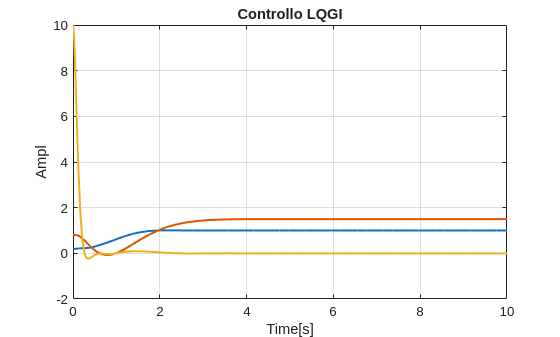

% Plot MATLAB
out = sim('Verifica_LQR_DE6000008.slx');
y_lqr = out.y.Data;
time = out.y.Time;

figure
plot(time, y_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
title('Controllo LQGI');

## CONTROLLO LQGI

#### Specifiche 

W = 1e-3*eye(n);
V = 1e-4*eye(3);

Qv = W;
Rv = V;

#### Sistema Perturbato

G = eye(n);

sys_perturbato = ss(A, [B G], C, zeros(size(C,1), size([B G],2)))


sys_perturbato =
 
  A = 
          x1     x2     x3     x4     x5     x6
   x1      0      0      0      1      0      0
   x2      0      0      0      0      1      0
   x3      0      0      0      0      0      1
   x4      0      0  -9.81      0      0      0
   x5      0      0      0      0      0      0
   x6      0      0      0      0      0      0
 
  B = 
           u1      u2      u3      u4      u5      u6      u7      u8
   x1       0       0       1       0       0       0       0       0
   x2       0       0       0       1       0       0       0       0
   x3       0       0       0       0       1       0       0       0
   x4       0       0       0       0       0       1       0       0
   x5  0.6667       0       0       0       0       0       1       0
   x6       0      40       0       0       0       0       0       1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
 
  D = 


#### Filtro di Kalman

% Guadagno di Kalman
[~, L, ~] = kalman(sys_perturbato, Qv, Rv);

A_kf = A - L*C;
B_kf = [B L];
C_kf = eye(n);
D_kf = zeros(size(C_kf,1), size(B_kf,2));

KF = ss(A_kf, B_kf, C_kf, D_kf)


KF =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1      -5.436  -6.248e-16      0.9584           1           0           0
   x2    -1.3e-15       -4.04   7.856e-16           0           1           0
   x3      0.9584  -1.814e-15      -3.919           0           0           1
   x4      -10.23   3.971e-15      -1.217           0           0           0
   x5   3.796e-16      -3.162  -4.363e-16           0           0           0
   x6      0.3734  -1.272e-15       -3.14           0           0           0
 
  B = 
               u1          u2          u3          u4          u5
   x1           0           0       5.436   6.248e-16     -0.9584
   x2           0           0     1.3e-15        4.04  -7.856e-16
   x3           0           0     -0.9584   1.814e-15       3.919
   x4           0           0       10.23  -3.971e-15      -8.593
   x5      0.6667           0  -3.796e-16       3.162   4.363e-16
   x6           0          40     

#### Verifica Simulazione

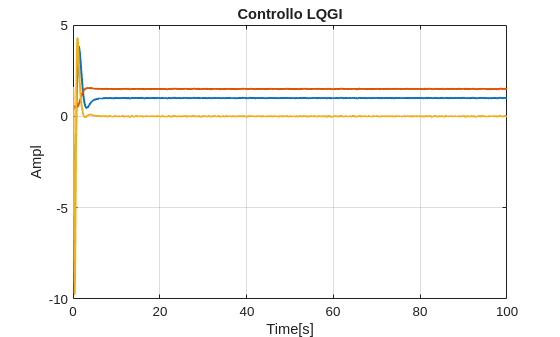

% Plot MATLAB
out = sim('Verifica_LQG_DE6000008.slx');
y_lqg = out.y.Data;
vel = out.vel.Data;
time = out.y.Time;

figure
plot(time, y_lqg, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
title('Controllo LQGI');

## SVD

#### Lettura dell'immagine e conversione in scala di grigi

I_orig = imread('immagine_svd_drone.png');
I_gray = rgb2gray(I_orig);
I = double(I_gray);

#### Immagine Originale in scala di grigi

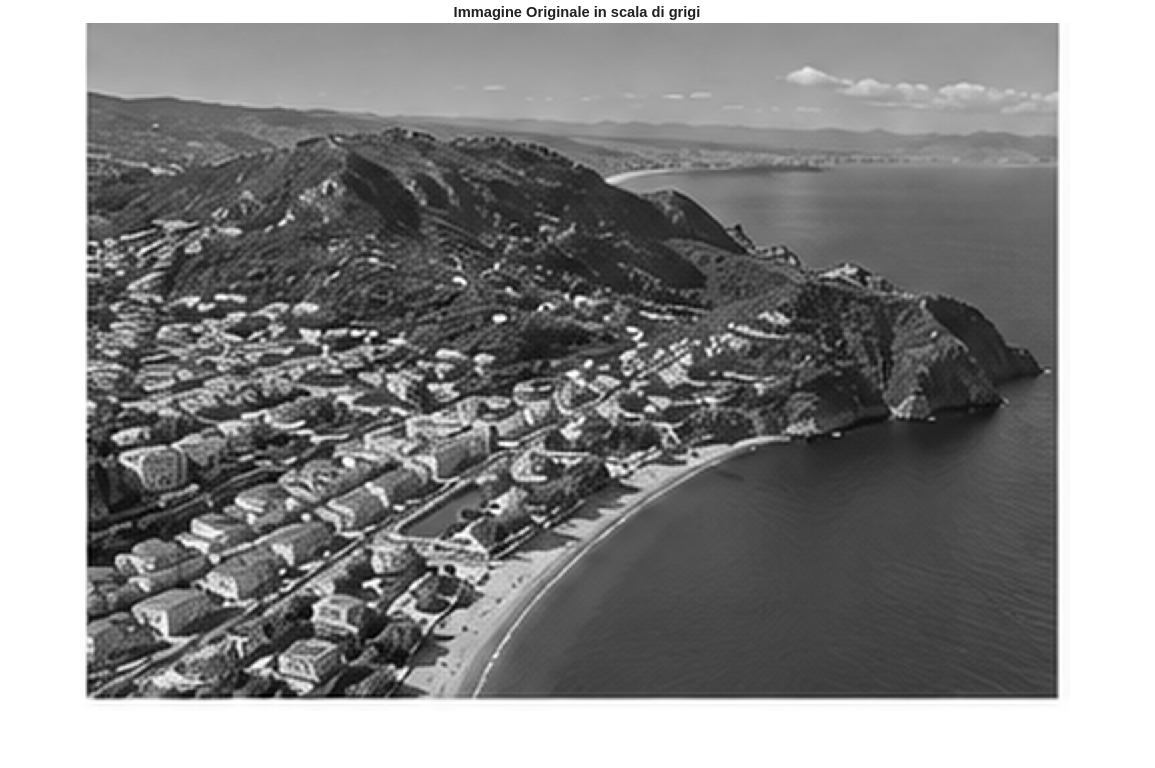

figure;
imshow(uint8(I_gray));
title('Immagine Originale in scala di grigi');

#### Decomposizione SVD

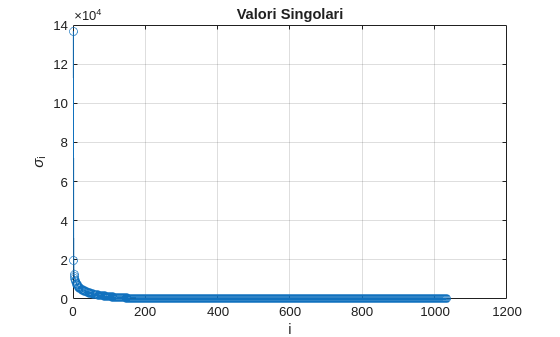

[U, S, V] = svd(I, 'econ');
singvals = diag(S);

figure;
plot(singvals, 'o-');
title('Valori Singolari');
xlabel('i');
ylabel('\sigma_i');
grid on;

#### Compressione 

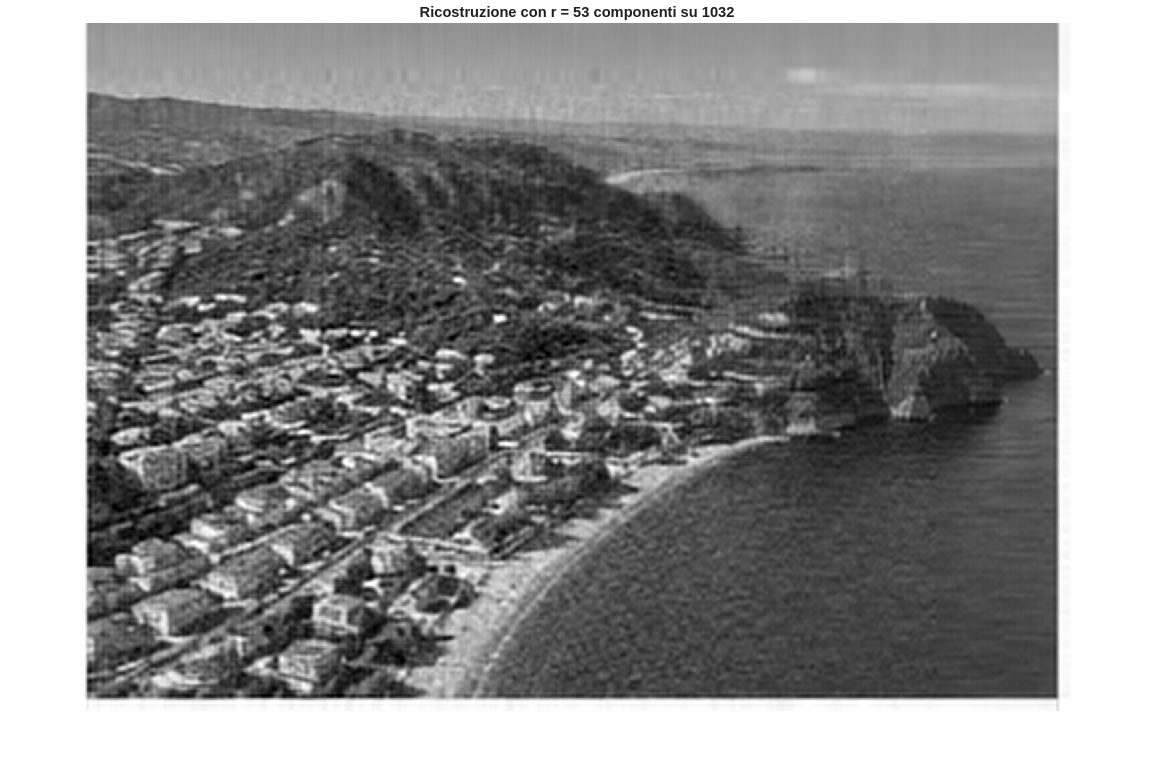

sigma_max = singvals(1);
soglia = 0.01*sigma_max;

% Cerchiamo l'indice dell'ultimo valore singolare che rispetta la
somma_tot = sum(singvals.^2); 
somma_parz = 0; r = 0; 

for i = 1:length(singvals) 
    somma_parz = somma_parz + singvals(i)^2; 
    if (somma_parz / somma_tot) >= 0.99        
        r = i; break; 
    end
end

% Ricostruiamo l'immagine usando solo le prime r componenti
U_r = U(:,1:r);
S_r = S(1:r,1:r);
V_r = V(:,1:r);

% Ricostruzione Immagine Compressa
I_compressa = U_r*S_r*V_r';

figure;
imshow(uint8(I_compressa));
title(sprintf('Ricostruzione con r = %d componenti su %d', r, length(singvals)));

### Rapporto di Compressione e Errore di Ricostruzione

#### Rapporto di Compressione 

m_i = size(I,1);
n_i = size(I,2);

num_originale = m_i * n_i *3;
num_compressa = r*(m_i+n_i+1)*3;
tasso_compr = 100*(1-num_compressa/num_originale);
fprintf('Rapporto di Compressione = %.4f%%\n', tasso_compr);

Rapporto di Compressione = 91.2798%


#### Errore di Ricostruzione 

err = norm(I - I_compressa, 'fro') / norm(I, 'fro');
fprintf('Errore relativo (Frobenius) = %.4f\n', err);

Errore relativo (Frobenius) = 0.0996
